# Calcolo Numerico con Laboratorio 

# Compito a casa 

# 15 novembre 2021

## Esercizio 1

Sia $R$ il rettangolo $[-1,3]\times[-2,2]$. Si consideri il seguente sistema lineare:


$$\left\{\begin{array}{l}
f(x,y)=(y^2+2x^2-2x-2)^2-2x-1=0\\
g(x,y)=y-x+1=0
\end{array}\right. \quad \text{per }(x,y)\in R
$$


- Rappresentare la superficie $f(x,y)$  nel rettangolo $R$.

- Rappresentare le curve di livello 0 delle funzioni $f$ e $g$ in $R$.

- Trovare tutte le soluzioni del sistema usando `fsolve `e marcarle sul grafico contente le curve di livello 0.

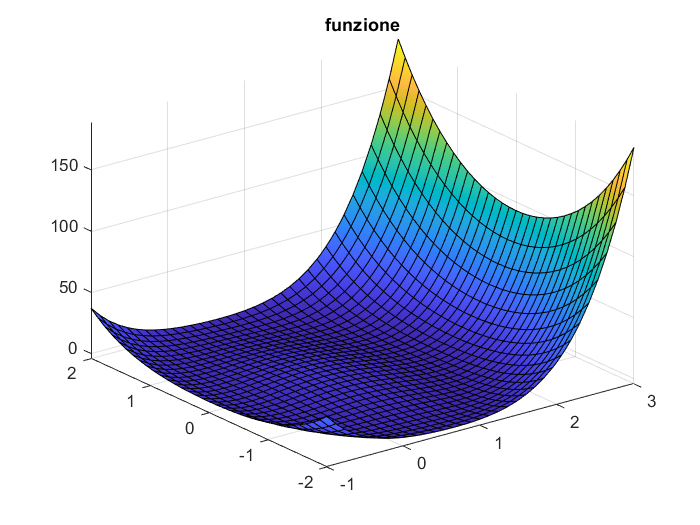

clear all
close all
xInterval=[-1,3];yInterval=[-2,2];
f=@(x,y) (y.^2+2*x.^2-2*x-2).^2 -2*x -1;
g=@(x,y) y-x+1;
fsurf(f,[xInterval yInterval])
title("funzione")
savefig("Es1_fun")

fcontour(f,[xInterval yInterval],'LevelList',0)
hold on
fcontour(g,[xInterval yInterval],'LevelList',0)
legend("f","g")
F=@(x) [f(x(1),x(2));g(x(1),x(2))];
[zm,Fm]=fsolve(F,[1,0]);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


plot(zm(1),zm(2),'or')
[zm,Fm]=fsolve(F,[3,2]);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


plot(zm(1),zm(2),'or')
[zm,Fm]=fsolve(F,[-1,-2]);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


plot(zm(1),zm(2),'or')
[zm,Fm]=fsolve(F,[0,-1]);


Equation solved at initial point.

fsolve completed because the vector of function values at the initial point
is near zero as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


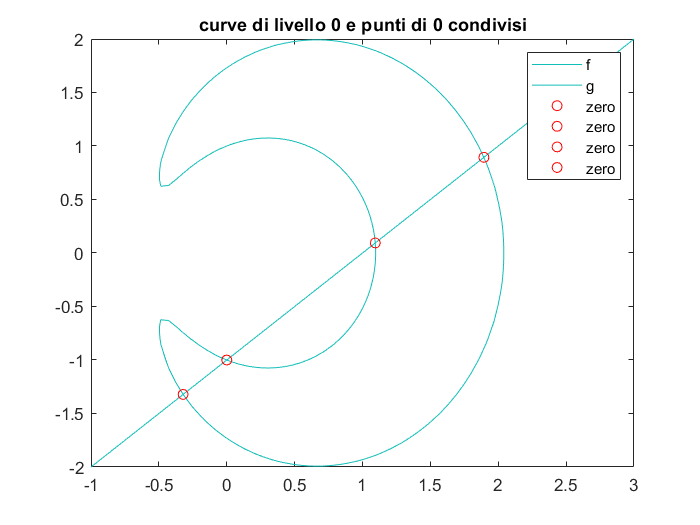

plot(zm(1),zm(2),'or')
legend("f","g","zero","zero","zero","zero")
title("curve di livello 0 e punti di 0 condivisi")
savefig("Es1_zeri")

## Esercizio 2

Si consideri la funzione

$f(x,y)=3(1-x)^2\,e^{-x^2 - (y+1)^2} - 10\left(\frac x5 - x^3 - y^5\right)e^{-x^2-y^2}- \frac13e^{-(x+1)^2 - y^2}$.

- Fare il grafico della superficie  e delle curve di livello sul quadrato di lato $[-3,3]$.

- Scegliendo opportunamente il dato iniziale determinare i punti di minimo relativo della funzione e riportarli nella figura insieme alle curve di livello.

- Trovare inoltre i punti di massimo relativo.

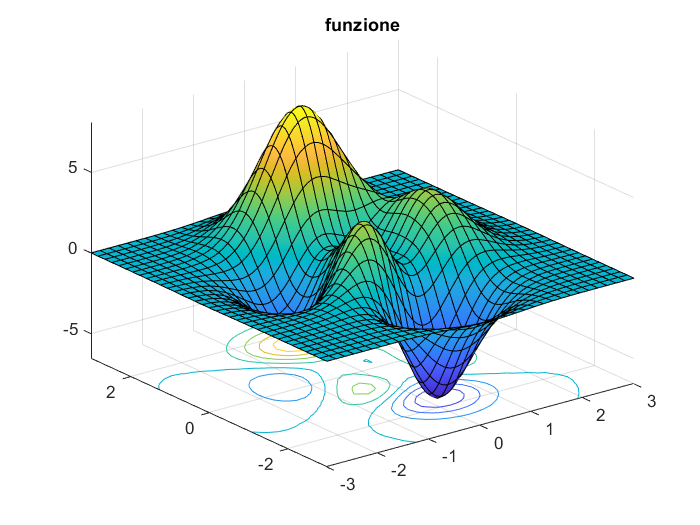

clear all
close all
f=@(x,y) 3*(1-x).^2.*exp(-x.^2-(y+1).^2)-10*(x./5-x.^3-y.^5).*exp(-x.^2-y.^2)-exp(-(x+1).^2-y.^2)./3;
fsurf(f,[-3 3],'ShowContours','on')
title("funzione")
savefig("Es2_funzione")

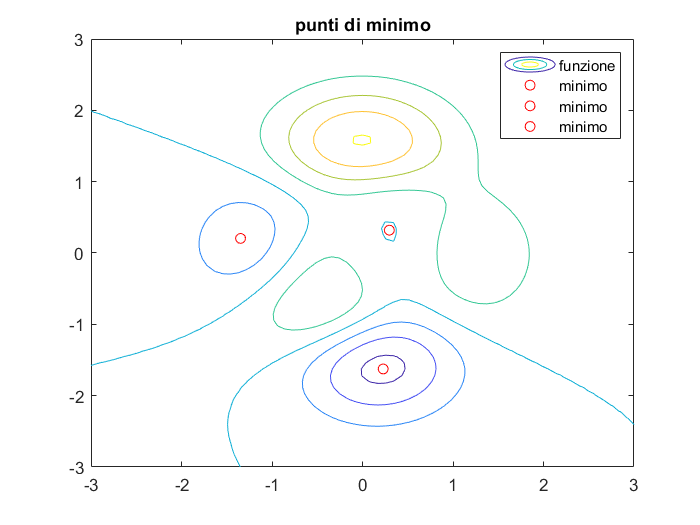

F=@(x) [f(x(1),x(2))];
m1=fminsearch(F,[0;-2]);
m2=fminsearch(F,[-2;0]);
m3=fminsearch(F,[0.5;0.5]);
fcontour(f,[-3 3])
hold on
plot(m1(1),m1(2),'or')
plot(m2(1),m2(2),'or')
plot(m3(1),m3(2),'or')
hold off
title("punti di minimo")
legend("funzione","minimo","minimo","minimo")
savefig("Es2_minimi")

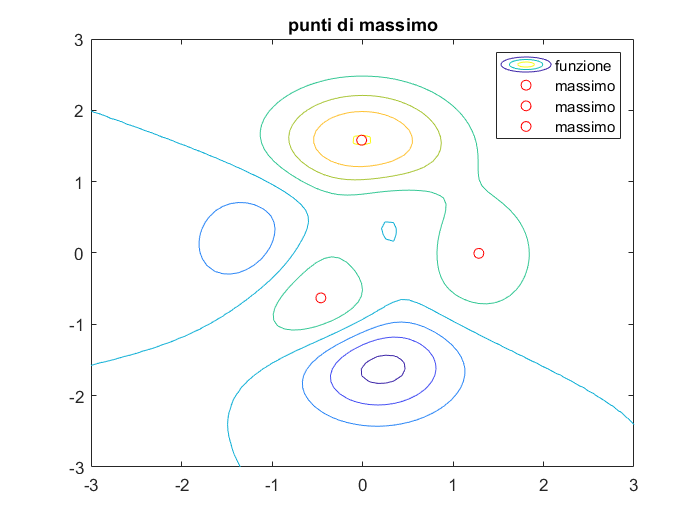

Fn=@(x) [-f(x(1),x(2))];
m1=fminsearch(Fn,[-1;-1]);
m2=fminsearch(Fn,[-1;2]);
m3=fminsearch(Fn,[1;0]);
fcontour(f,[-3 3])
hold on
plot(m1(1),m1(2),'or')
plot(m2(1),m2(2),'or')
plot(m3(1),m3(2),'or')
legend("funzione","massimo","massimo","massimo")
title("punti di massimo")
savefig("Es2_massimi")

## Esercizio 3

Si consideri la funzione $f(x,y)=(y^2+2x^2-2x-2)^2 -2x-1$.

Fare il grafico della funzione nel rettangolo $[-1,2]\times[-2,2]$.

Calcolare il minimo assoluto della funzione usando come punto iniziale `x0=[1.5;0.5] `e riportare il risultato ottenuto in un grafico insieme alle curve di livello. Per vedere più dettagli nel grafico delle curve di livello usare `LevelStep `uguale a` 0.5.`

Calcolare il minimo di $f$ soggetto al vincolo $x-y\le 1$e riportarlo in una figura insieme alle curve di livello di $f$ e alla rappresentazione del vincolo.

Calcolare il minimo di $f$ soggetto al vincolo $y+x^2\le 0$ e riportarlo in una figura insieme alle curve di livello di $f$ e alla rappresentazione del vincolo.

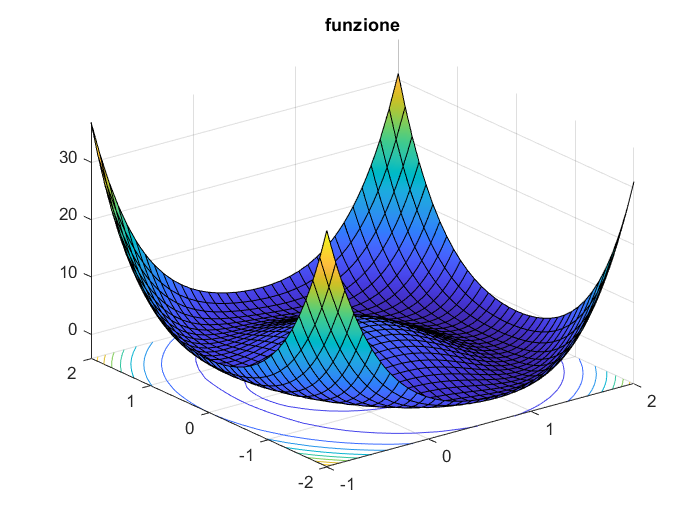

clear all
close all
f=@(x,y) (y.^2+2*x.^2-2*x-2).^2-2*x-1;
fsurf(f,[[-1,2] [-2 2]],'ShowContours','on')
title("funzione")
savefig("Es3_funzione")

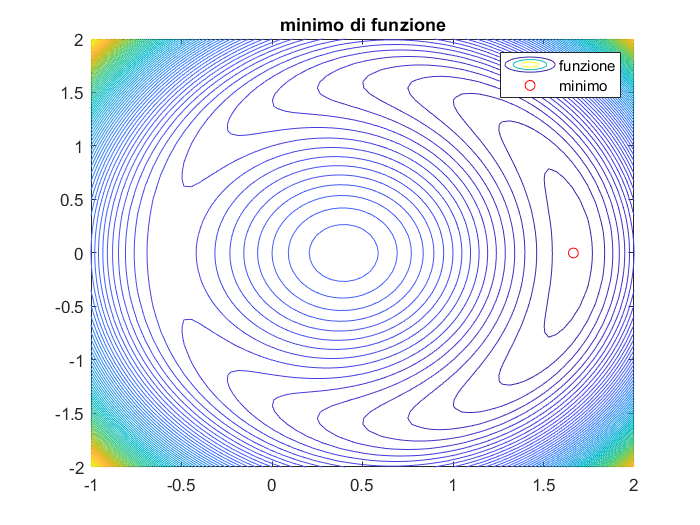

x0=[1.5;0.5];
F=@(x) [f(x(1),x(2))];
[zm,fm]=fminsearch(F,x0);
fcontour(f,[[-1,2] [-2 2]],'LevelStep',0.5)
hold on 
plot(zm(1),zm(2),'or')
hold off
title("minimo di funzione")
savefig("Es3_minimo")
legend("funzione","minimo")

A=[1 -1];b=1;
g=@(x,y) x-y-1;
m1=fmincon(F,x0,A,b);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


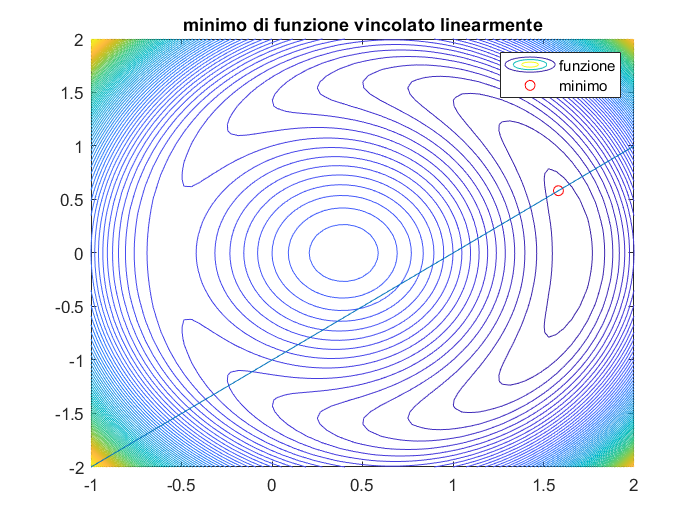

fcontour(f,[[-1,2] [-2 2]],'LevelStep',0.5)
hold on 
plot(m1(1),m1(2),'or')
fimplicit(g,[[-1,2] [-2 2]])
title("minimo di funzione vincolato linearmente")
savefig("Es3_minimo_vincolatoL")
legend("funzione","minimo")

figure
m1=fmincon(F,x0,[],[],[],[],[],[],@(x) limit(x));


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


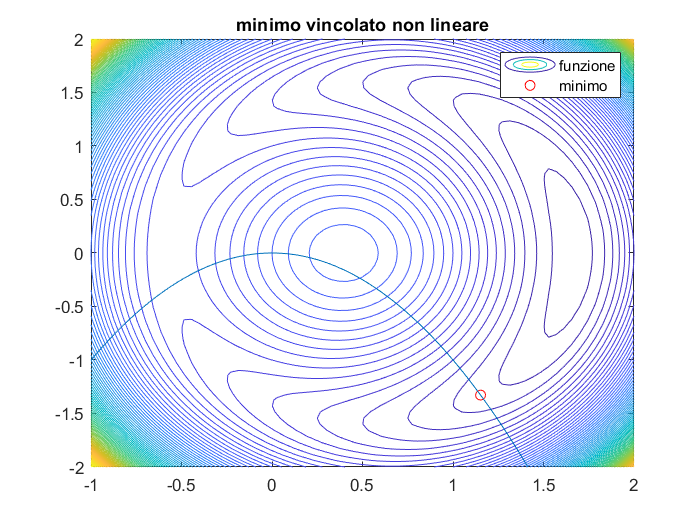

fcontour(f,[[-1,2] [-2 2]],'LevelStep',0.5)
hold on 
plot(m1(1),m1(2),'or')
f=@(x,y) y+x.^2;
fimplicit(f,[[-1,2] [-2 2]])
title("minimo vincolato non lineare")
legend("funzione","minimo")
savefig("Es3_minimo_vincolatNonL")